# Fit of X-band data sample 1b

clearvars; close all
% Path to the project folder
chdir('D:\Profile\qse\files\projects\sijia_sulphurization');
% Add source file directory
addpath(genpath('scr'));

## Import

load('data/processed/gm-e1-0034.mat');

## Fit 2 spin systems

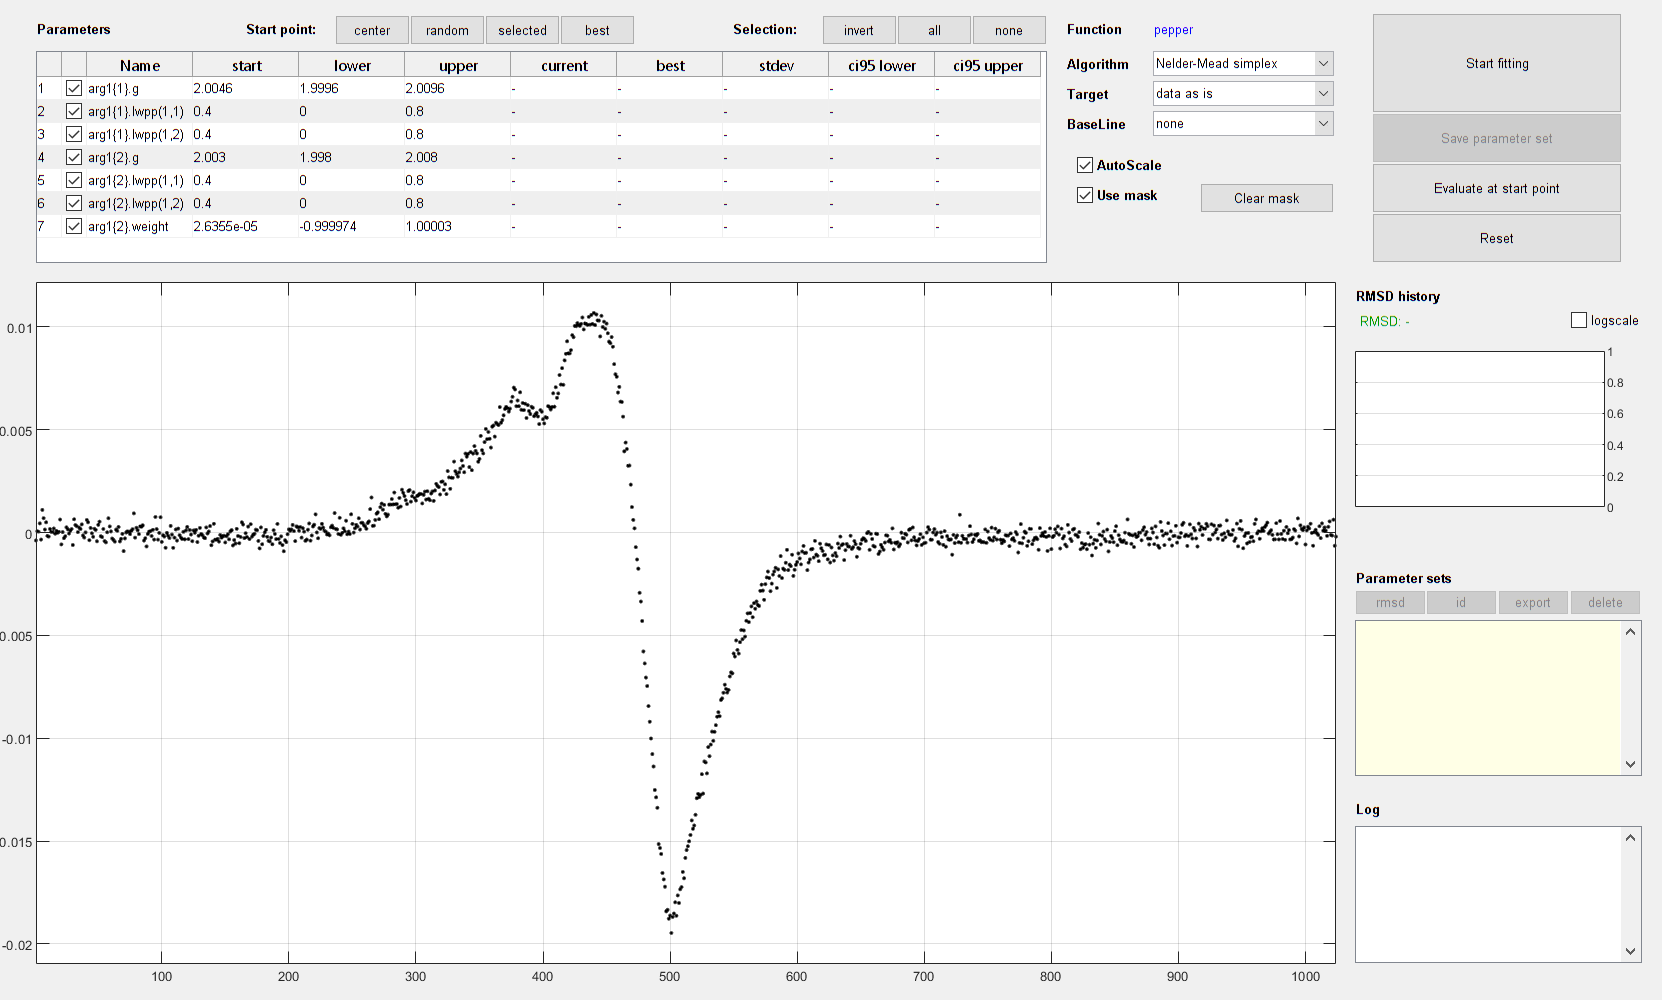

Sys0 = struct('g', 2.0046, ...
    'lwpp', [0.4 .4]);
Sys1 = struct('g', 2.003, ...
    'lwpp', [0.4 0.4], ...
    'weight', 2.6355e-5);

Vary0 = struct('g', .005, ...
    'lwpp', Sys0.lwpp);
Vary1 = struct('g', .005, ...
    'lwpp', Sys1.lwpp, ...
    'weight', 1);

% Define x and y
Exp.Range = [min(cw.x) max(cw.x)];
Exp.mwFreq = cw.Params.MWFQ*1e-9;
Exp.nPoints = numel(cw.x);

% Disregard low field peak g ~ 2.0065
% FitOpt.mask = (1:numel(x) < 195) | (1:numel(x) > 378);
FitOpt.BaseLine = [];

Sys = {Sys0, Sys1};
SysVary = {Vary0, Vary1};

% Fit = esfit(yy, @pepper, {{Sys1, Sys2, Sys3}, Exp}, {{Vary1, Vary2, Vary3}}, FitOpt)
esfit(cw.y, @pepper, {Sys, Exp}, {SysVary}, FitOpt);

### Immediately save the fit

Dir.SPath = 'data/processed/gm20230622_sample4_Qband_mwpw_18dB_fit.mat';
% Title = '2023-06-22 sample 4 Qband mwpw 18dB fit';
% save(Dir.SPath, 'Fit', 'Title');

### Simulate separate components and save again afterwards

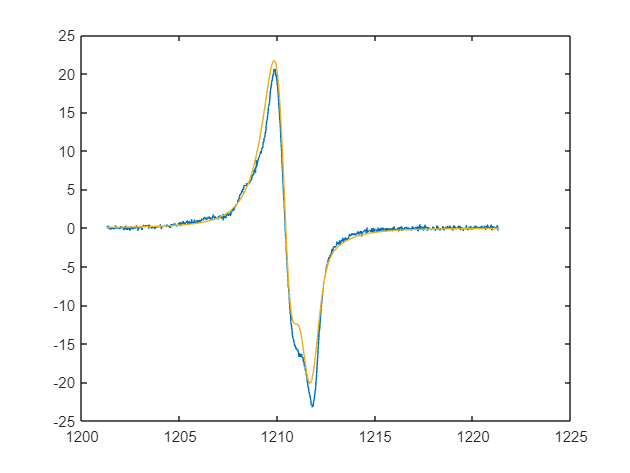

Dir.LPath = 'data/processed/gm20230622_sample4_Qband_mwpw_18dB_fit.mat';
load(Dir.LPath)

Sys0b.g = Fit.pfit(1);
Sys0b.lwpp(2) = Fit.pfit(2);
Sys1b.g = Fit.pfit(3);
Sys1b.lwpp(1) = Fit.pfit(4);
Sys1b.weight = Fit.pfit(5);

Exp = Fit.argsfit{1, 2};
Opt.Output = 'separate';

yFit = Fit.scale*pepper({Sys0b, Sys1b}, Exp, Opt);
Fit.yFit0 = yFit(1, :);
Fit.yFit1 = yFit(2, :);

% Save again
% Title = '2023-06-22 sample 4 Qband mwpw 18dB fit';
% save(Dir.SPath, 'Fit', 'Title');
figure()
plot(cw(5).x, -real(cw(5).y2))
hold on
plot(cw(5).x, Fit.fit)
plot(cw(5).x, Fit.yFit0 + Fit.yFit1)

### Calculate weights

From the weights parameters of esfit, calculate the weigths u1 and u2 that summed are equal to 1.

format long
w1 = 1; % dw1 = 0
w2 = Fit.pfit(5); % Check if pfit(5) is a weight
dw2 = Fit.pstd(5);
u1 = w1/(w1 + w2)

u1 =    0.999973646961422


du1 = w1/((w1 + w2)^2) * dw2

du1 =      3.696408216331101e-06


u2 = w2/(w1 + w2)

u2 =      2.635303857749643e-05


du2 = (w1 + 2*w2)/((w1 + w2)^2) * dw2

du2 =      3.696603044642065e-06


The value obtained from u2 is extremely small!

Follows the same calculation but from the double integral:

DI1 = cumtrapz(cumtrapz(yFit(1, :)));
DI2 = cumtrapz(cumtrapz(yFit(2, :)));
w1 = DI1(end);
w2 = DI2(end);
u1DI = w1/(w1 + w2)

u1DI =    0.927382002691478


u2DI = w2/(w1 + w2)

u2DI =    0.072617997308522


These make more sense, but how to extract uncertainty?

fprintf(['g1 = %.5f +- %.5f\n', ...
    'lwpp1 = %.2f +- %.2f\n', ...
    'weight1 = %f +- ?\n' ...
    'g2 = %.5f +- %.5f\n' ...
    'lwpp2 = %.2f +- %.2f\n', ...
    'weight2 = %f +- ?'], ...
    [Fit.pfit(1), Fit.pstd(1), ...
     Fit.pfit(2), Fit.pstd(2), ...
     u1DI, ...
     Fit.pfit(3), Fit.pstd(3), ...
     Fit.pfit(4), Fit.pstd(4), ...
     u2DI])

g1 = 2.00459 +- 0.00003
lwpp1 = 1.12 +- 0.02
weight1 = 0.927382 +- ?
g2 = 2.00296 +- 0.00004
lwpp2 = 0.84 +- 0.04
weight2 = 0.072618 +- ?

## Fit 3 spin systems

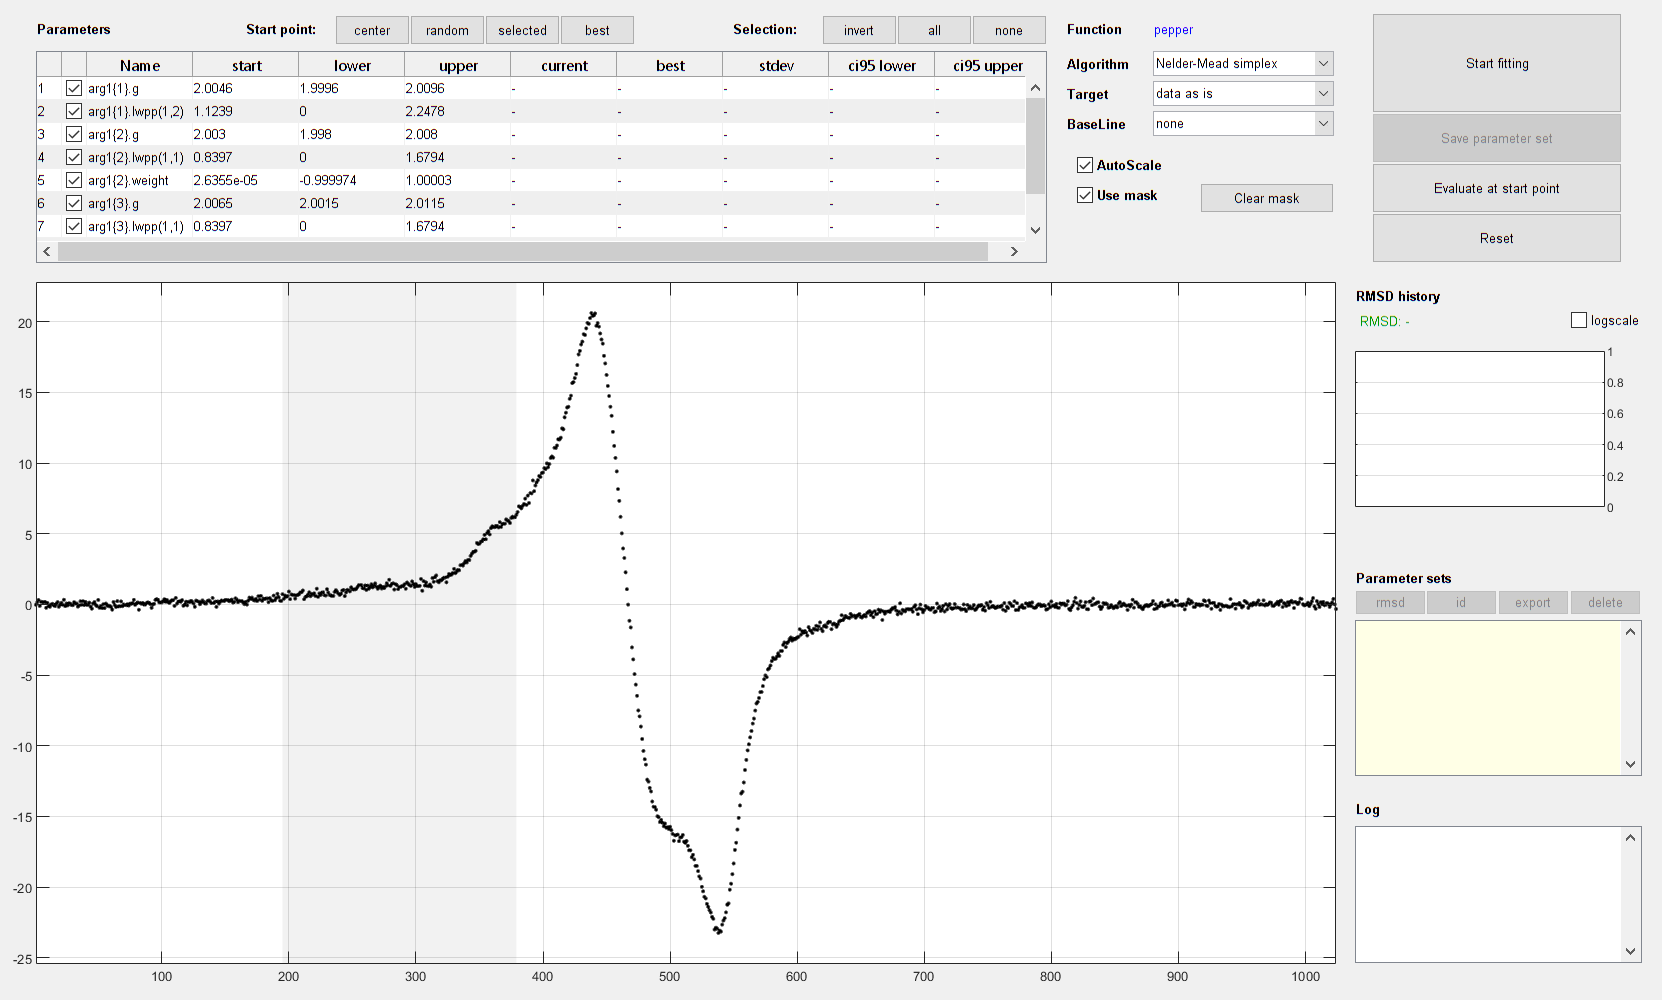

ICW = 5;
Sys0 = struct('g', 2.0046, ...
    'lwpp', [0. 1.1239]);
Sys1 = struct('g', 2.003, ...
    'lwpp', [0.8397 0.], ...
    'weight', 2.6355e-5);
Sys2 =  struct('g', 2.0065, ...
    'lwpp', [0.8397 0.5], ...
    'weight', 0.0005);

Vary0 = struct('g', .005, ...
    'lwpp', Sys0.lwpp);
Vary1 = struct('g', .005, ...
    'lwpp', Sys1.lwpp, ...
    'weight', 1);
Vary2 = struct('g', .005, ...
    'lwpp', Sys2.lwpp, ...
    'weight', 1);

Exp.Range = [min(cw(ICW).x) max(cw(ICW).x)];
Exp.mwFreq = cw(ICW).Params.MWFQ*1e-9;
Exp.nPoints = numel(cw(ICW).x);

MaskL = 1:numel(cw(ICW).x) < 195;
MaskR = 1:numel(cw(ICW).x) > 378;
Mask = logical(MaskL + MaskR);
FitOpt.mask = Mask;

Sys = {Sys0, Sys1, Sys2};
SysVary = {Vary0, Vary1, Vary2};

% Fit = esfit(yy, @pepper, {{Sys1, Sys2, Sys3}, Exp}, {{Vary1, Vary2, Vary3}}, FitOpt)
esfit(-real(cw(ICW).y2), @pepper, {Sys, Exp}, {SysVary}, FitOpt);